clear all
close all
data = load('usps_all');
data = cell2mat(struct2cell(data));

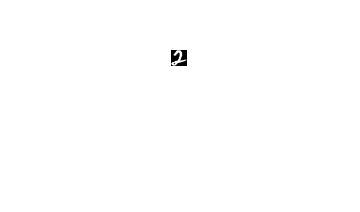

imshow(reshape(data(:,100,2),[16 16]),[]); %shows specific image

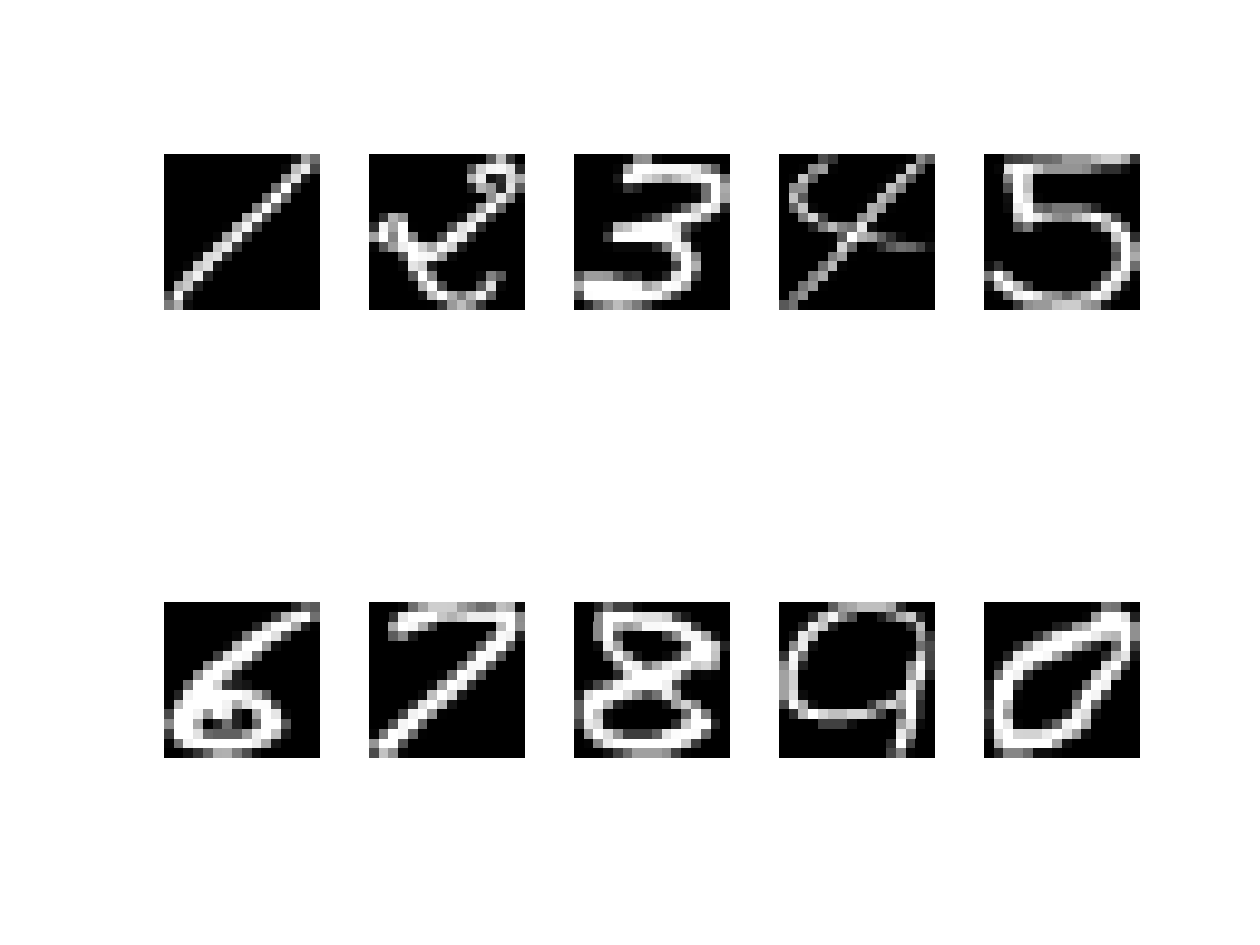

figure;

for i = 1:10
    subplot(2,5,i);
    imshow(reshape(data(:,5,i),[16 16]),[]);
end

figure;


## Problem 1

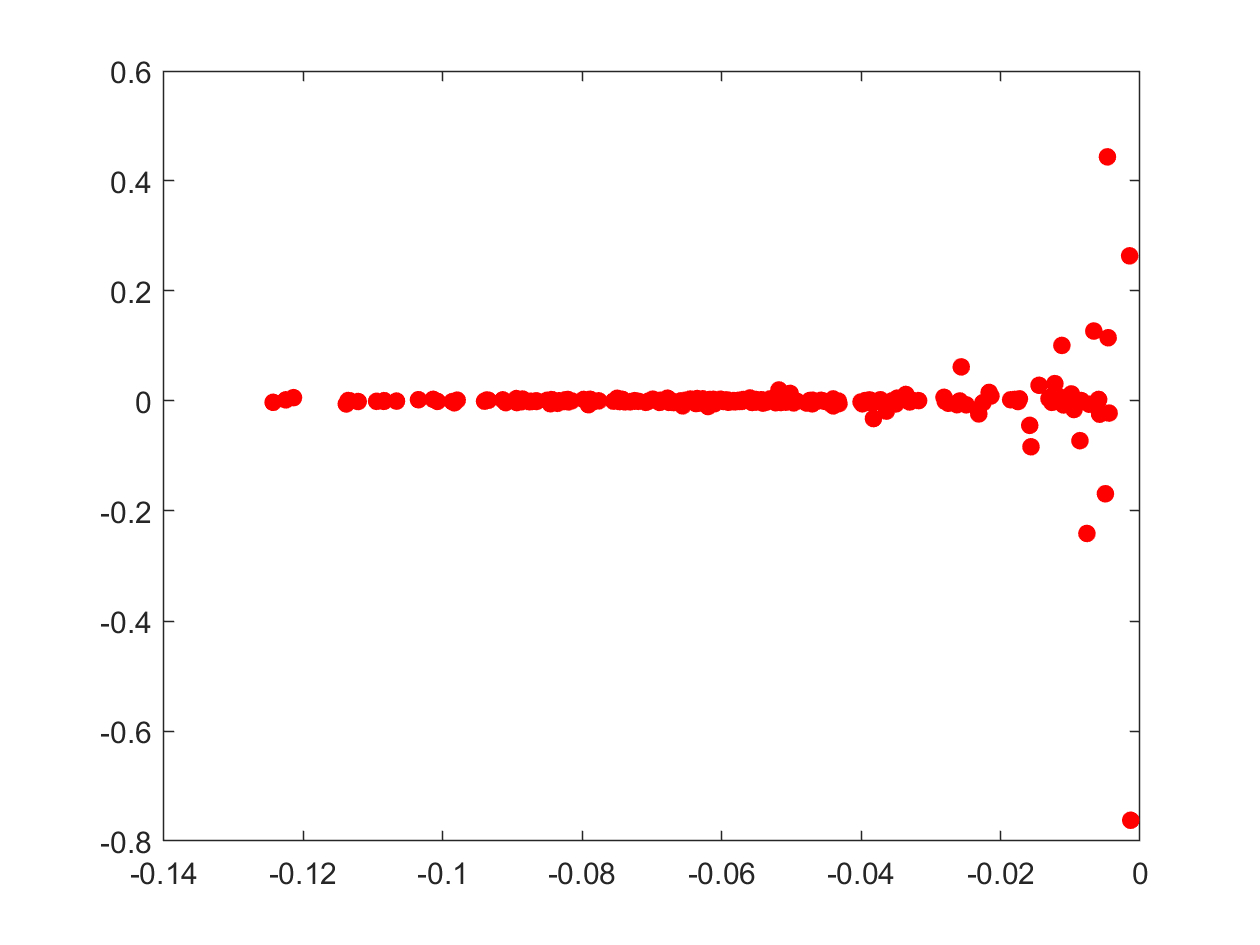

%Use MatlabUse Matlab's pca function to find principal components of the dataset of 
%handwritten digits collected by USPS. 

[pix,d1,d2] = size(data);
X = zeros(pix,d1*d2);

for j = 1:pix
    aux = data(j,:,:);
    X(j,:) = aux(:)';
end

[U,Sig,V] = svd(X','econ');
nPCA = 256;
% project to nPCA-dimensional space
Y = X*U(:,1:nPCA);

figure;
plot(V(:,1),V(:,256),'.','Markersize',20,'color','r');
view(2);

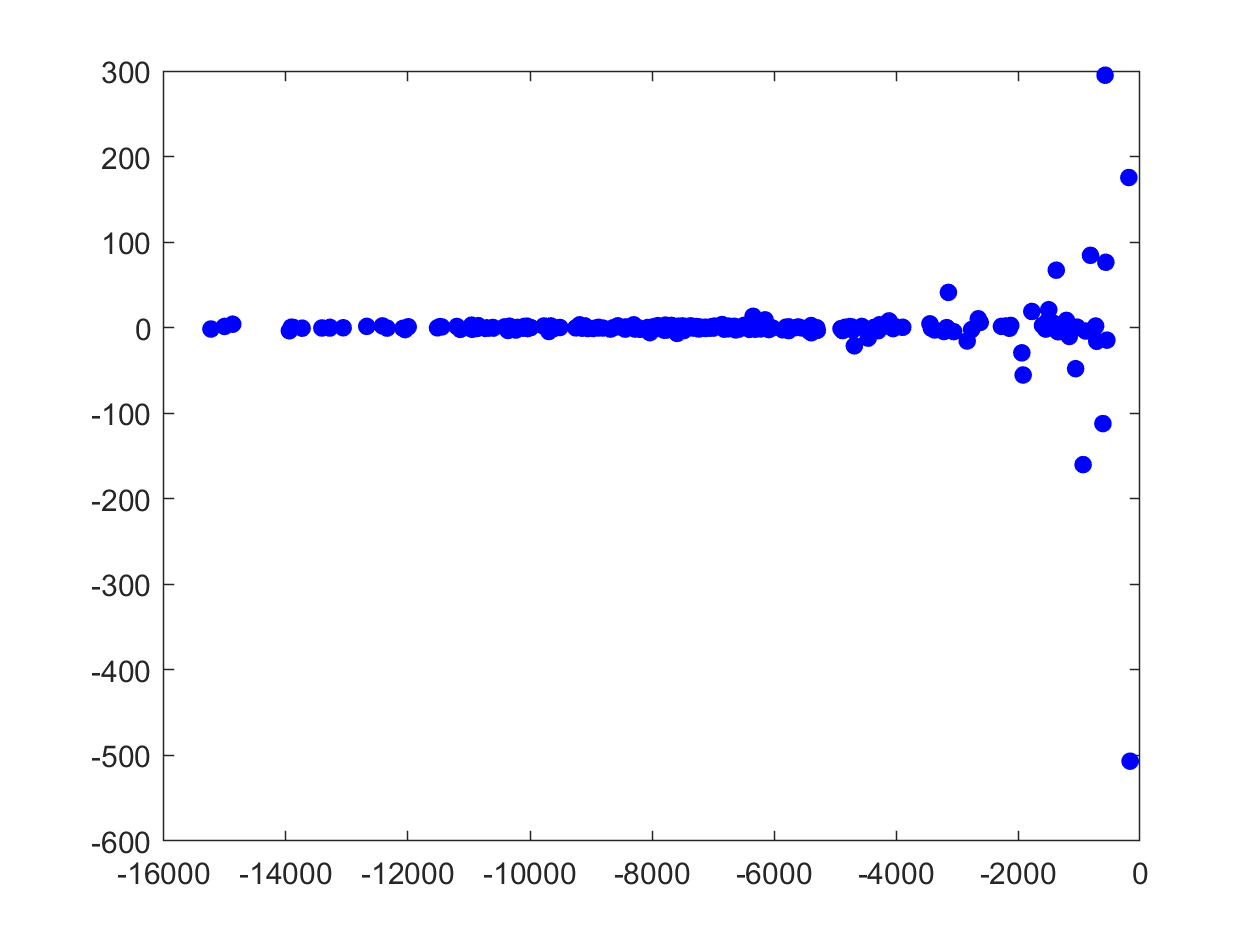



figure;
plot(Y(:,1),Y(:,256),'.','Markersize',20,'color','b');

## **Problem 2**

% signals = Y *data;
%imshow(reshape(Y(:,1),[16 16]),[]);

Y1 = Y(1,:)

Y1 =  -162.7277   33.6227 -167.5148   33.5742  -87.3132 -115.3287  131.8979   -7.9712   54.2336  -79.9249   68.5619  -81.7044   72.0713  -30.7588   23.7201  -40.0780  154.2835   -3.3072  -22.4338 -103.9436  -89.1429   60.4410 -171.4446   24.6669  -45.6555   78.2905  -43.4149  120.2021  -46.1593    0.1070  -19.8944   20.0209  -38.0286   54.8741  -34.2994   11.3445  -28.2225   50.8471   18.2185  142.3143  -92.0237   99.0583  -85.3717   62.2995   79.2368   17.0848   77.3383 -130.6783   -6.8540   53.0754


Y2 = Y(2,:)

Y2 =  -559.9313   74.5914 -545.3206  199.2527 -333.4824 -439.7407  416.1362   58.1024  205.6464 -240.0603  245.6285 -231.2858  183.7574 -226.5678  113.2328 -121.9641  494.2082   -8.0087 -177.0748 -347.7556 -173.7521  134.0076 -538.2814  164.6250 -101.2080  322.5832 -121.4930  422.8481 -193.6358   19.7289    5.3947  152.9492 -128.4998  173.2380  -78.0962   77.8004  -88.2897  165.6134  145.6307  424.2471 -360.8772  271.3045 -263.6116  225.6551  281.8068   14.8853  252.6235 -381.3374   17.5073   75.1088


mu1 = mean(Y1,1)

mu1 =  -162.7277   33.6227 -167.5148   33.5742  -87.3132 -115.3287  131.8979   -7.9712   54.2336  -79.9249   68.5619  -81.7044   72.0713  -30.7588   23.7201  -40.0780  154.2835   -3.3072  -22.4338 -103.9436  -89.1429   60.4410 -171.4446   24.6669  -45.6555   78.2905  -43.4149  120.2021  -46.1593    0.1070  -19.8944   20.0209  -38.0286   54.8741  -34.2994   11.3445  -28.2225   50.8471   18.2185  142.3143  -92.0237   99.0583  -85.3717   62.2995   79.2368   17.0848   77.3383 -130.6783   -6.8540   53.0754


mu2 = mean(Y2,1)

mu2 =  -559.9313   74.5914 -545.3206  199.2527 -333.4824 -439.7407  416.1362   58.1024  205.6464 -240.0603  245.6285 -231.2858  183.7574 -226.5678  113.2328 -121.9641  494.2082   -8.0087 -177.0748 -347.7556 -173.7521  134.0076 -538.2814  164.6250 -101.2080  322.5832 -121.4930  422.8481 -193.6358   19.7289    5.3947  152.9492 -128.4998  173.2380  -78.0962   77.8004  -88.2897  165.6134  145.6307  424.2471 -360.8772  271.3045 -263.6116  225.6551  281.8068   14.8853  252.6235 -381.3374   17.5073   75.1088


for j = 1:nPCA
    fprintf('%d\t%d\n',mu1(j), mu2(j));
end

-1.627277e+02	-5.599313e+02
3.362268e+01	7.459141e+01
-1.675148e+02	-5.453206e+02
3.357419e+01	1.992527e+02
-8.731325e+01	-3.334824e+02
-1.153287e+02	-4.397407e+02
1.318979e+02	4.161362e+02
-7.971203e+00	5.810236e+01
5.423361e+01	2.056464e+02
-7.992485e+01	-2.400603e+02
6.856193e+01	2.456285e+02
-8.170442e+01	-2.312858e+02
7.207132e+01	1.837574e+02
-3.075884e+01	-2.265678e+02
2.372005e+01	1.132328e+02
-4.007800e+01	-1.219641e+02
1.542835e+02	4.942082e+02
-3.307165e+00	-8.008746e+00
-2.243385e+01	-1.770748e+02
-1.039436e+02	-3.477556e+02
-8.914286e+01	-1.737521e+02
6.044098e+01	1.340076e+02
-1.714446e+02	-5.382814e+02
2.466689e+01	1.646250e+02
-4.565554e+01	-1.012080e+02
7.829049e+01	3.225832e+02
-4.341485e+01	-1.214930e+02
1.202021e+02	4.228481e+02
-4.615927e+01	-1.936358e+02
1.069962e-01	1.972886e+01
-1.989439e+01	5.394707e+00
2.002088e+01	1.529492e+02
-3.802859e+01	-1.284998e+02
5.487407e+01	1.732380e+02
-3.429937e+01	-7.809616e+01
1.134450e+01	7.780045e+01
-2.822253e+01	-8.828967e+0

fprintf('norm(mu1-mu2) = %d\n',norm(mu1-mu2));

norm(mu1-mu2) = 2.325265e+03


Z = Y*X

Z = 	1.0e+06 *

    0.1597    0.1033    0.1500    0.1717    0.0763    0.1219    0.0883    0.1157    0.1781    0.1092    0.0911    0.2409    0.1285    0.1310    0.1365    0.0833    0.1047    0.1335   -0.1843    0.0163    0.0851    0.2406    0.0671    0.1910   -0.1569    0.1024    0.0963   -0.1422    0.1162    0.1306   -0.2367    0.1068    0.1075    0.0798    0.1430    0.1560    0.1004    0.1231    0.1513    0.1960    0.1543    0.1724    0.0850    0.0863    0.1153    0.1418    0.1210    0.1099    0.0590    0.0899
    0.2923   -0.2727   -0.0258   -0.0208    0.0878   -0.0057   -0.0602   -0.1925    0.0854    0.2142   -0.0408   -0.1006   -0.0555   -0.0203    0.2137    0.1159    0.0104    0.1640   -0.2974    0.0273    0.1208    0.1110   -0.1688    0.1262   -0.2779    0.0934   -0.0005   -0.1575    0.1690    0.0405   -0.3043    0.0565    0.0230    0.1649    0.0135   -0.0587    0.2772    0.2040   -0.1782   -0.0102    0.0528   -0.0655    0.0760    0.1288    0.2686    0.1531    0.1161   -0.0354   

newdata = Y*Z

newdata = 	1.0e+10 *

   -0.0486   -0.0570    0.0022   -0.0127   -0.0527   -0.0380   -0.0273   -0.0004   -0.0109   -0.0287   -0.0120   -0.0582   -0.0311   -0.0107   -0.0404   -0.0184   -0.0128   -0.0279    0.0564   -0.0461   -0.0298   -0.0449   -0.0698   -0.0069   -0.0213    0.0342   -0.0029   -0.0086   -0.0416   -0.0420   -0.1078   -0.0292   -0.0220   -0.0430   -0.0098   -0.0498   -0.0679   -0.0561   -0.0199    0.0100   -0.0206   -0.0017   -0.0357   -0.0536   -0.0406   -0.0581   -0.0558   -0.0163   -0.0737    0.0015
    0.0134   -0.0513    0.0678    0.0818   -0.0089    0.0409   -0.0207    0.0092    0.0854    0.0219    0.0605   -0.0624    0.0798    0.0618    0.0269    0.0141    0.0800    0.0571   -0.0070    0.0522    0.0065    0.0027   -0.0115    0.0908   -0.0327    0.1838    0.1207    0.0816   -0.0174    0.0749   -0.0788    0.0413    0.0787   -0.0126   -0.0041   -0.0807   -0.0228    0.0046   -0.0173    0.0580    0.0735    0.0296    0.0128   -0.0414    0.0145   -0.0134   -0.0011    0.0

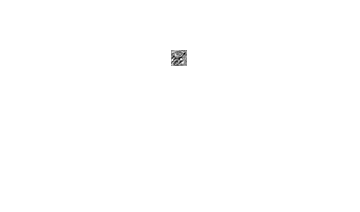

imshow(reshape(newdata(:,1),[16 16]),[]); %shows specific image

figure;

set = newdata(:,1:1101:end)

set = 	1.0e+10 *

   -0.0486   -0.0092   -0.0233    0.0303   -0.0017    0.0663   -0.1762   -0.0068    0.0032    0.0316
    0.0134   -0.0381    0.0836    0.0563   -0.0376    0.0365   -0.0579    0.0374   -0.0312    0.0840
    0.1676   -0.0012    0.2084    0.1910    0.0109   -0.2123    0.1513    0.2216    0.1330    0.1173
   -0.0405   -0.1824    0.0522    0.0899   -0.1268   -0.3037   -0.1517   -0.0417    0.1720   -0.1982
   -0.2910   -0.1783   -0.2553    0.1049   -0.0230   -0.1417   -0.1458   -0.3341    0.2469   -0.4952
   -0.1246    0.1371   -0.1011    0.0699    0.1770    0.1029    0.3124   -0.1632    0.2655   -0.1246
    0.1806    0.2405    0.3591    0.1540    0.3937    0.3042    0.0564    0.0583    0.4141    0.2484
   -0.1085   -0.1195    0.2494    0.2197    0.3365   -0.0483   -0.0765   -0.0392    0.3197   -0.2613
   -0.2911    0.3902    0.1782    0.3805    0.4030    0.2580   -0.0300    0.1925    0.4619   -0.1176
    0.1568    0.6322    0.4319    0.3359    0.4090    0.3336    0.0972   

## **Problem 2**

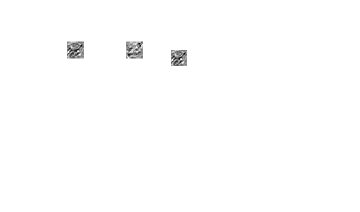

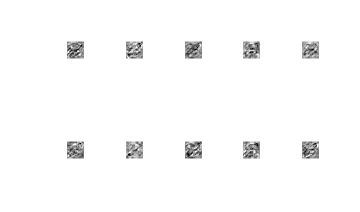

imshow(reshape(set(:,1),[16 16]),[]);

for l = 1:10
    subplot(2,5,l);
    imshow(reshape(set(:,l),[16 16]),[]);
end

## Problem 3


trainset = [];
testset = [];
train_labels = [];



Ntrain = 550

Ntrain = 550

Ntest = d1-Ntrain

Ntest = 550

train1 = 1:Ntrain

train1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


train2 = (d1+1):(d1+Ntrain);
train3 = (d1+d1+1):(d1+Ntrain+Ntrain+Ntrain);
train4 = (d1+d1+d1+1):(d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);
train5 = (d1+d1+d1++d1+1):(d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);
train6 = (d1+d1+d1++d1+d1+1):(d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);
train7 =(d1+d1+d1++d1+d1+d1+1):(d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);
train8 = (d1+d1+d1+d1++d1+d1+d1+1): (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);
train9 = (d1+d1+d1+d1++d1+d1+d1+d1+1):(d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);
train0 = (d1+d1+d1+d1++d1+d1+d1+d1+d1+1):(d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain);

test1 = (Ntrain+1):d1

test1 =    551   552   553   554   555   556   557   558   559   560   561   562   563   564   565   566   567   568   569   570   571   572   573   574   575   576   577   578   579   580   581   582   583   584   585   586   587   588   589   590   591   592   593   594   595   596   597   598   599   600


test2 = (d1+Ntrain+1):(2*d1);
test3 = (d1+Ntrain+Ntrain+Ntrain+1):(3*d1);
test4 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(4*d1);
test5 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(5*d1);
test6 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(6*d1);
test7 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(7*d1);
test8 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(8*d1);
test9 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(9*d1);
test0 = (d1+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+Ntrain+1):(10*d1);

train_idx = [train1,train2,train3,train4,train5,train6,train7,train8,train9,train0];
test_idx = [test1, test2, test3, test4, test5,test6,test7,test8, test9, test0];
Ytrain = newdata(:,train_idx);
Ytest = newdata(:,test_idx);

mea = mean(Ytrain,1);
mean2 = mean(Ytest,1);
n1 = 550;
n2 = 550;
%Y1 = Y(1,:)
%Y2 = Y(2,:)
%mu1 = mean(Y1,1)
%mu2 = mean(Y2,1)

Y1c = Y1-ones(n1,1)*mu1; %center the data in class1
Y2c = Y2-ones(n2,1)*mu2; %center the data in class2
S1 = Y1c'*Y1c/n1;
S2 = Y2c'*Y2c/n2;


Yallc = Y1 - ones(n1,1)* mea;

Matrix dimensions must agree.

Yallc2 = Y2 - ones(n2,1)*mean2;
newS1 = Yallc'*Yallc/n1;
newS2 = Yallc2'*Yallc2/n2;
